# **                                                                                                                                                                                                                                                                                                                    Modelo 10Khz Conmutable**

clc 
clear
close all
warning off
% Parámetros del conversor Buck
P_nom_buck = 120;         % Potencia nominal en vatios (W)
Vg = 24;           % Tensión de entrada en voltios (V)
Vout_buck = 12;          % Tensión de salida en voltios (V)

%F_sw=3e3 sirve bien
f_sw = 6e3            % Frecuencia de conmutación en hercios (Hz)

f_sw = 6000


% fsim= 117*f_sw
fsim=300e3

fsim = 300000

%frecuencia de simulacion 300 0 350khz

Tsim=1/fsim

Tsim = 3.3333e-06

Tsw=1/f_sw

Tsw = 1.6667e-04

R = Vout_buck^2/P_nom_buck % Nominal load. CCM

R = 1.2000

P1= P_nom_buck*0.5;
R1=Vout_buck^2/P1;
P2= P_nom_buck*0.6;
R2=Vout_buck^2/P2;
P3= P_nom_buck*0.8;
R3=Vout_buck^2/P3;
t1=250e-3

t1 = 0.2500

t2=160e-3

t2 = 0.1600

t3=350e-3

t3 = 0.3500

t2prima=350e-3

t2prima = 0.3500

% Ripples Based on nominal parameters
% Delta_IL_buck = 0.4;
Delta_Vout_buck = 0.05*Vout_buck

Delta_Vout_buck = 0.6000


% Cálculo de la corriente de salida del Buck
Iout_buck = P_nom_buck / Vout_buck;
Delta_IL_buck = Iout_buck*0.3

Delta_IL_buck = 3


% Cálculo del ciclo de trabajo (Duty Cycle) del Buck
D_Buck = Vout_buck / Vg;


% Cálculo de la inductancia del Buck
L_buck = (Vg - Vout_buck) / (f_sw * Delta_IL_buck) * D_Buck

L_buck = 3.3333e-04


% Cálculo de la capacitancia del Buck
C_buck1 = ((1 / f_sw) * (Delta_IL_buck / 2)) / (8 * (Delta_Vout_buck / 2))

C_buck1 = 1.0417e-04


F_cutLPF = 1/(2*pi*sqrt(L_buck*C_buck1));


Scaling_Voltage = (1/Vout_buck)*(2^12)/(3);
% Scaling current to get 1 v at the output.
Scaling_Current = (1/Iout_buck)*(2^12)/(3);


% ---------------------------
% Parámetros C variable suave
% ---------------------------
C_buck1

C_buck1 = 1.0417e-04

ic=Delta_IL_buck;
deltat=5*Tsw;
deltav=0.1*Vout_buck;
C_2=(ic*deltat)/deltav

C_2 = 0.0021

C_buck=C_2

C_buck = 0.0021


%%%%%% PI Control design
% PI Controller design

Num=Vg;
Den=[(L_buck*C_buck) L_buck/R1 1];

g=tf(Num,Den)


g =
 
                24
  -------------------------------
  6.944e-07 s^2 + 0.0001389 s + 1
 
Continuous-time transfer function.


[C_pi,info] = pidtune(g,'PI')


C_pi =
 
        1 
  Ki * ---
        s 

  with Ki = 3.44
 
Continuous-time I-only controller.


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 83.0620
           PhaseMargin: 89.3359


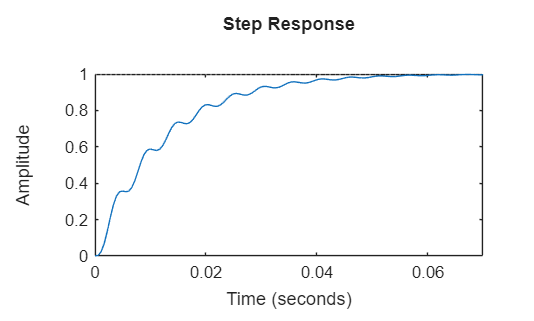

T_pi = feedback(C_pi*g, 1);
step(T_pi)



C_pi.Kp

ans = 0

C_pi.Ki  

ans = 3.4446





% conf_step = RespConfig('InputOffset',0,'StepAmplitude',0.4167);
% step(g,conf_step)
% grid on
% 
% G=feedback(g,1)
% stepinfo(G)
% bode(G)

%%%%%%%%%%%%%%


TBPRD =round(200e6/(2*f_sw));

SimTime = 500e-3;        % Simulation Time
% RelativeTolerance: Es la tolerancia relativa de la simulacion en 
% continuo


% Select the simulation option
% Choose CCM
% Choose BCM
% Choose DCM
SimulationType = 'CCM'

SimulationType = 'CCM'


switch SimulationType
    case 'CCM'
        R = Vout_buck^2/P_nom_buck; % Nomila load. CCM
%         R = 3;
        % SimTime = 150e-3;
        RelativeTolerance = 1e-5;
    case 'BCM'
        Icritic = Delta_IL_buck/2
%       R = 50; % Increased to BCM
        R = Vout_buck/Icritic % Increased to BCM

        % SimTime = 150e-3;
        RelativeTolerance = 1e-6;
    case 'DCM'
        R = 100; % Increased to BCM
        % SimTime = 150e-3;
        RelativeTolerance = 1e-10;
end



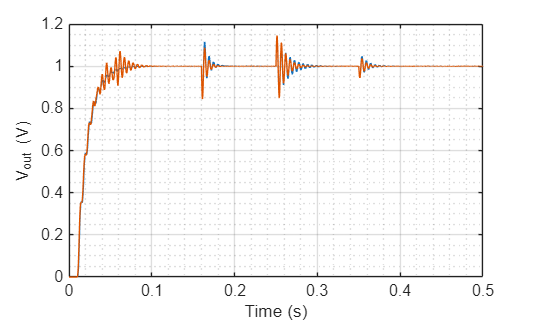

% Continuous Simulation
load_system("ContinuosBuck_Offine_Control.slx");

% block_path = gcb;    % Function to know the route of a block
% allparam = get_param('ContinuosBuck_Offine_Control/Integral3','ObjectParameters')

set_param('ContinuosBuck_Offine_Control/Integral3', 'P', num2str(C_pi.Kp));
set_param('ContinuosBuck_Offine_Control/Integral3', 'I', num2str(C_pi.Ki));

sim("ContinuosBuck_Offine_Control.slx")
tiledlayout(3,1)

ax1 = nexttile;
plot(ax1,ResultCont{1}.Values.Time, ResultCont{1}.Values.Data(:,1))
ylabel(ax1,'V_o_u_t (V)')
grid on
grid minor

ax2 = nexttile;
plot(ax2,ResultCont{1}.Values.Time, ResultCont{1}.Values.Data(:,2))
ylabel(ax2,'I_i_n_d (A)')
grid on
grid minor

ax3 = nexttile;
plot(ax3,ResultCont{1}.Values.Time, ResultCont{1}.Values.Data(:,3))
ylabel(ax3,'Duty')
xlabel(ax3,'Time (s)')
grid on
grid minor


%%%%%%%%%%%%
% Discrete Simulation


block_path1 = 'DiscreteBuck_Offline_Control/Buck Converter Swich Model/Discrete-Time Integrator';
block_path2 = 'DiscreteBuck_Offline_Control/Buck Converter Swich Model/Discrete-Time Integrator1';
block_path_Control = 'DiscreteBuck_Offline_Control/Integral1';

% Types of integrators
% Type_Integrator = 'Forward Euler';
% Type_Integrator = 'Backward Euler';
Type_Integrator = 'Trapezoidal';

load_system("DiscreteBuck_Offline_Control.slx");
set_param(block_path1, 'IntegratorMethod', Type_Integrator);
set_param(block_path2, 'IntegratorMethod', Type_Integrator);

set_param('DiscreteBuck_Offline_Control/Integral1', 'P', num2str(C_pi.Kp));
set_param('DiscreteBuck_Offline_Control/Integral1', 'I', num2str(C_pi.Ki));


sim("DiscreteBuck_Offline_Control.slx")
figure
tiledlayout(3,1)

ax1 = nexttile;
plot(ax1,ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,1))
ylabel(ax1,'V_o_u_t (V)')
grid on
grid minor

ax2 = nexttile;
plot(ax2,ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,2))
ylabel(ax2,'I_i_n_d (A)')
grid on
grid minor

ax3 = nexttile;
plot(ax3,ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,3))
ylabel(ax3,'Duty')
xlabel(ax3,'Time (s)')
grid on
grid minor



%%% Comparisson between Discrete and Continuous Simulation
close all
figure
plot(ResultCont{1}.Values.Time, ResultCont{1}.Values.Data(:,1),...
     ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,1))
grid on
grid minor
ylabel('V_o_u_t (V)')
xlabel('Time (s)')

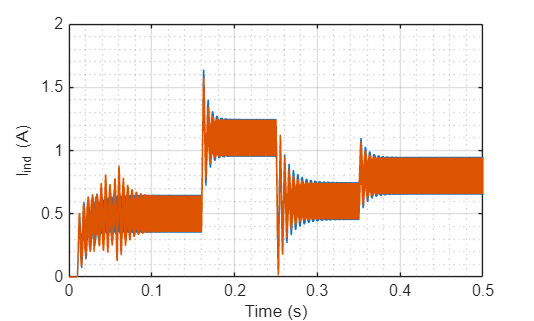


figure
plot(ResultCont{1}.Values.Time, ResultCont{1}.Values.Data(:,2),...
     ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,2))
grid on
grid minor
ylabel('I_i_n_d (A)')
xlabel('Time (s)')

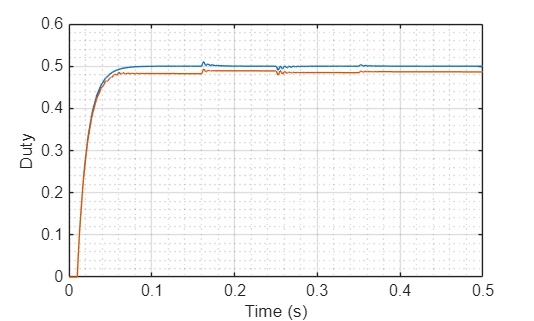


figure
plot(ResultCont{1}.Values.Time, ResultCont{1}.Values.Data(:,3),...
     ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,3))
grid on
grid minor
ylabel('Duty')
xlabel('Time (s)')

# Subida de datos reales

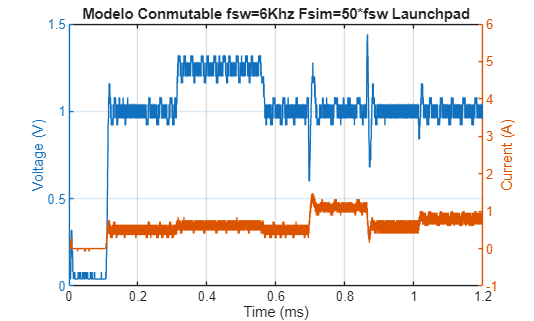

load("Caso2_1.mat")
% --- Datos del osciloscopio ---
ch1 = Caso2_1(:,2);  % Canal de voltaje
ch2 = Caso2_1(:,3);  % Canal de corriente

n = 300000; % número de puntos
muestras = 250e3; % tasa de muestreo en Hz (2.50 MSa/s)
T = 1 / muestras; % intervalo entre cada muestra
t_osc = (0:n-1) * T; % vector de tiempo desde 0 hasta el último punto

% Filtrado de los datos del osciloscopio (suavizado)
windowSize = 15; 
ch1_filtrado = movmean(ch1, windowSize); % Filtrado del canal de voltaje
ch2_filtrado = movmean(ch2, windowSize); % Filtrado del canal de corriente

% % --- Datos de Simulink ---
% t_sim = Continuo{1}.Values.Time; % Tiempo del modelo de Simulink
% voltaje_sim = Continuo{1}.Values.Data(:,1); % Voltaje del modelo
% corriente_sim = Continuo{1}.Values.Data(:,2); % Corriente del modelo

%Graficar Datos Obtenidos mediante el osciloscopio
figure
yyaxis left
plot(t_osc,ch1)
ylabel('Voltage (V)')
yyaxis right
plot(t_osc,ch2)
ylim([-1 6])
ylabel('Current (A)')
xlabel('Time (ms)')
set(gca,'FontSize',8)
grid on
title('Modelo Conmutable fsw=6Khz Fsim=50*fsw Launchpad')

# Comparación datos Reales Online Vs simulación Discreta Offline

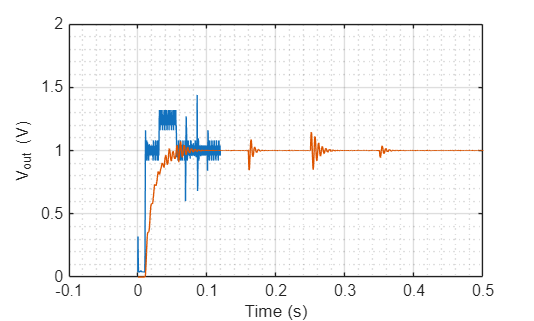

figure
plot((t_osc/10)-0.0007512,ch1_filtrado,...
     ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,1))
grid on
grid minor
ylabel('V_o_u_t (V)')
xlabel('Time (s)')
ylim([0 2])

xlim

ans =    -0.1000    0.5000


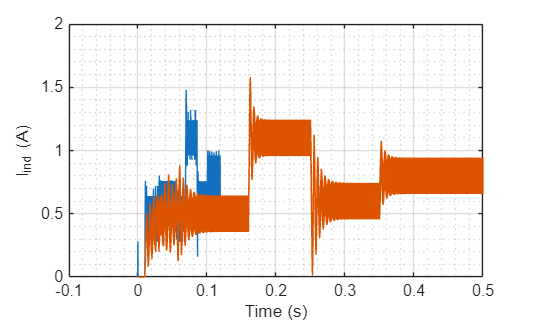


figure
plot((t_osc/10)-0.0007512,ch2_filtrado,...
     ResultDisc{1}.Values.Time, ResultDisc{1}.Values.Data(:,2))
grid on
grid minor
ylabel('I_i_n_d (A)')
xlabel('Time (s)')
ylim([0 2])

%xlim([-0.008  12*10e-3])
